**1 - Quadratic Approximation**

a) Given a function $f\left(x\right)=e^{x^2 +x}$ defined on the interval [−1,1], approximate it using Legendre polynomials up to degree N=2.

b) Analyze the accuracy of the approximation by computing the error, $\rho^2$.

#### Code for exercise number 1.

f = @(x) exp((x.^2)+x);
L = [-1,1];

fprintf('Exercise 1');

Exercise 1

Aproximation error: 7.5679


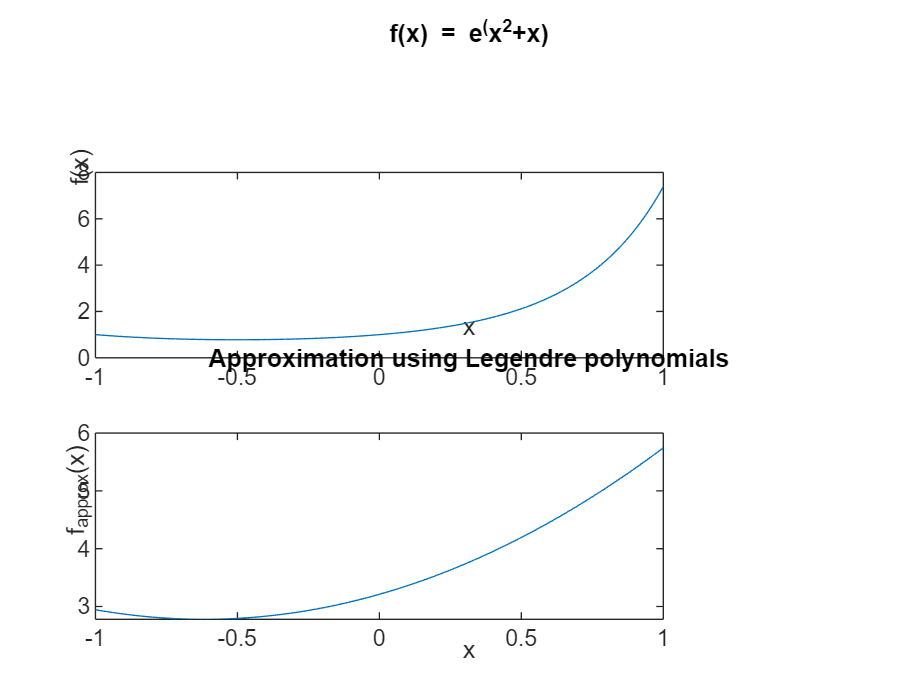

error = zad1(f, L);

**2 - Write a program to approximate the function **$f\left(x\right)=\mathrm{sin }\left(x\right)$** on the interval **$\left\lbrack 0,\pi \right\rbrack$** using point approximation with 6 points and a third degree of polynomial.**

a) Plot the original function and the polynomial approximation on the same graph.

b) Analyze the accuracy of the approximation by computing the maximum absolute error         between the original function and the polynomial approximation.

#### Code for exercise number 2.

g = @(x) sin(x);
L = [0 , pi];
n = 4; ...n is 4 because deegre 3th is 4th iteration
steps_e = 6;

fprintf('Exercise 2');

Exercise 2

S and T Table:
    1.0000         0         0         0         0
    1.0000    1.0472    1.0966    1.1484    0.8660
    1.0000    2.0944    4.3865    9.1870    0.8660
    1.0000    3.1416    9.8696   31.0063    0.0000



Approximation polynomial for 4th iteration:
f(x)=   -0.39486 x^2 + 1.2405 x
Approximation error: 0.017167


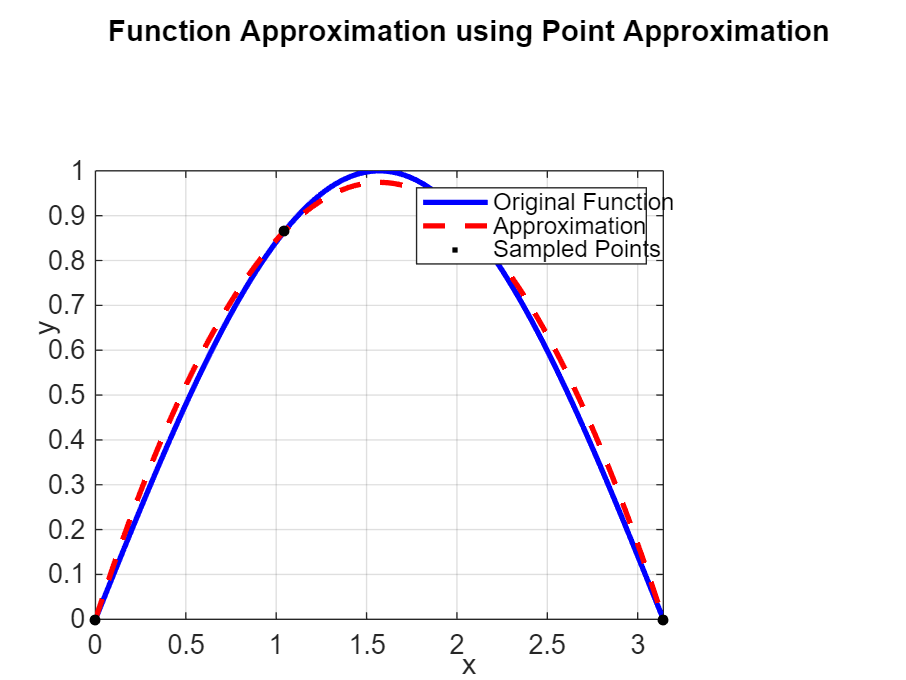


Approximation error: 0.0000


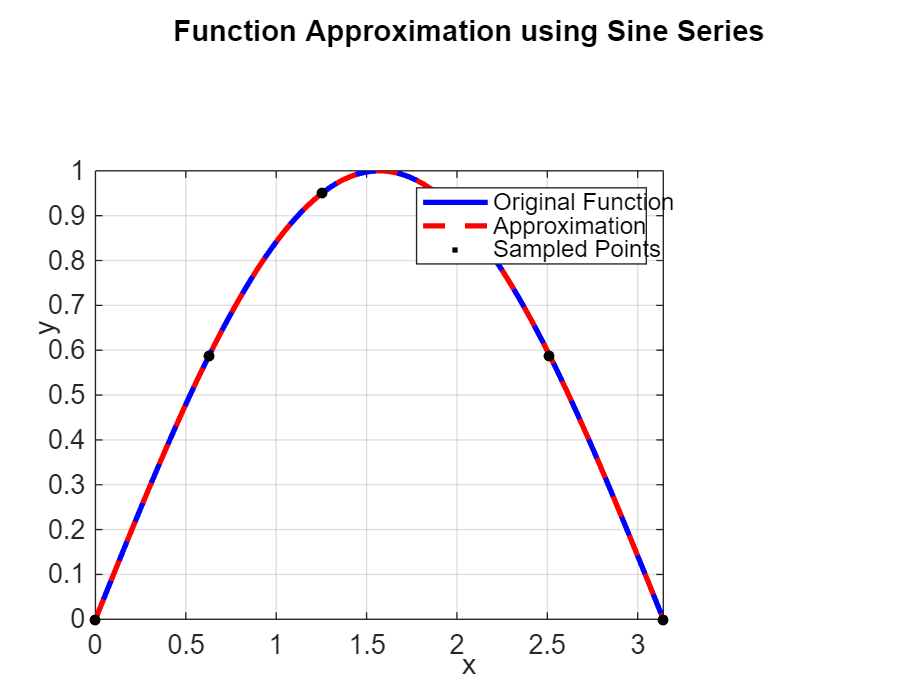

error = zad2_correct(g, L, n, steps_e); ...Point Approximation
error = zad2(g, L, n, steps_e); ...Sin Approximation

**3 - Write a program to approximate the function **$f\left(x\right)=e^{-x} \cdot \sin \left(\pi x\right)$** on the interval **$\left\lbrack 0,\pi \right\rbrack$** using point approximation with 6 points and varying degrees of polynomial from 1 to 4.**

a) Plot the original function and the approximations with the different degrees on the same graph.

b) Analyze the accuracy of each approximation by computing the maximum absolute error between the original function and the corresponding polynomial approximation.

#### Code for exercise number 3.

h = @(x) exp(-x).*sin(pi*x);
L = [0 , pi];
n = 5; ...n is 5 because deegre 4th is 5th iteration
steps_e = 6;

fprintf('Exercise 3');

Exercise 3



Approximation polynomial for 2th iteration:
f(x)=   -0.005919 x
Approximation error: 0.138458


Approximation polynomial for 3th iteration:
f(x)=   0.078407 x^2 - 0.25224 x
Approximation error: 0.165552


Approximation polynomial for 4th iteration:
f(x)=   -0.040939 x^3 + 0.19229 x^2 - 0.20598 x
Approximation error: 0.138622


Approximation polynomial for 5th iteration:
f(x)=   -0.29727 x^4 + 1.9332 x^3 - 3.8972 x^2 + 2.3748 x
Approximation error: 0.076126


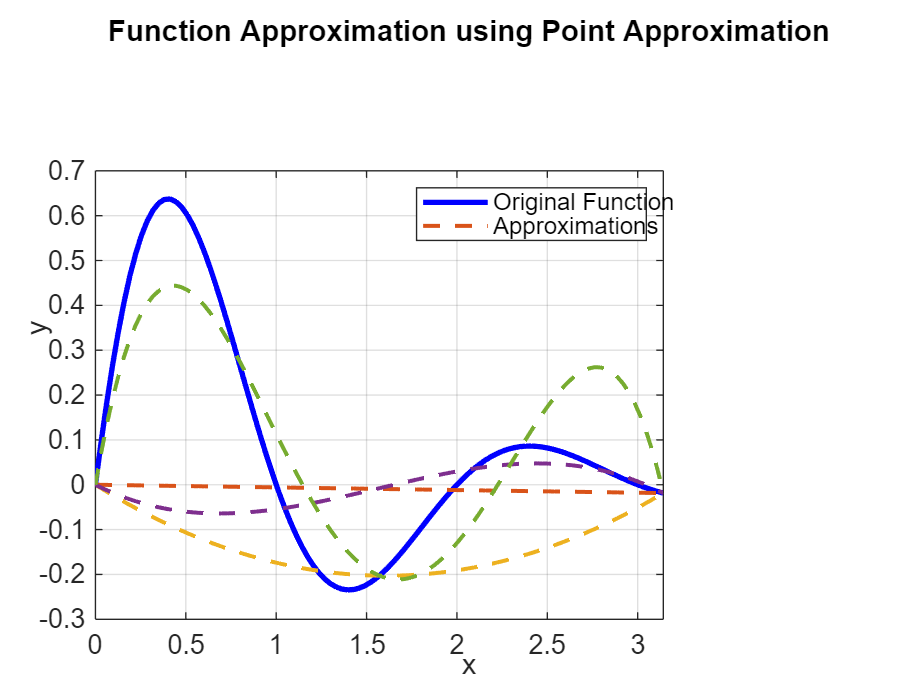

Approximation error 0.143159 for iteration = 2
Approximation error 0.077877 for iteration = 3
Approximation error 0.018452 for iteration = 4
Approximation error 0.018452 for iteration = 5


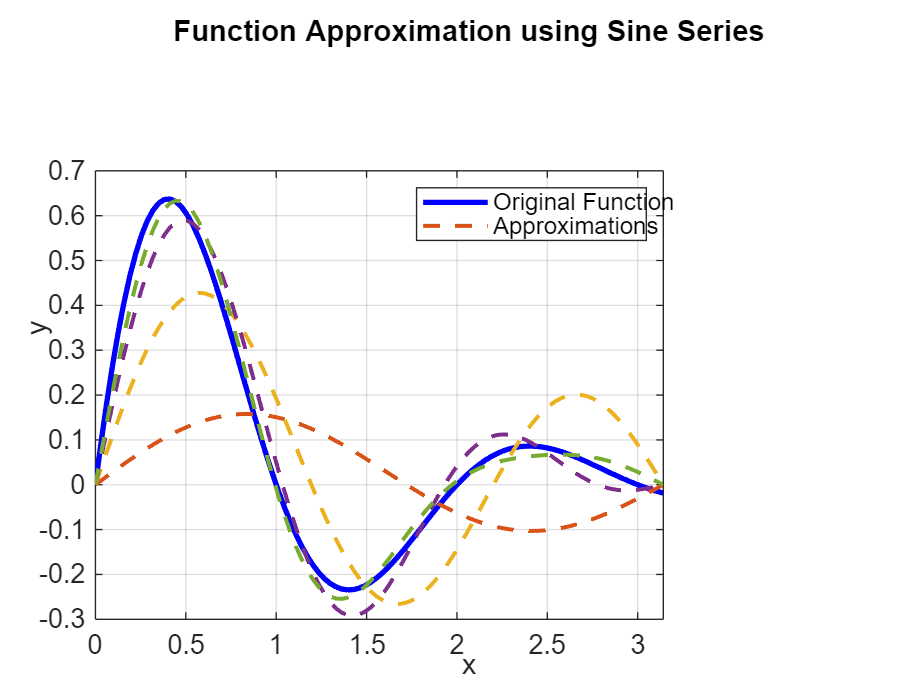

draw_ex3_correct(h, L, n, steps_e); ...Point Approximation
draw_ex3(h, L, n, steps_e); ...Sin Approximation

#### Functions:

function [error]=zad1(f, L); 
    P0 = @(x) ones(size(x));
    P1 = @(x) x;
    P2 = @(x) 0.5*(3*x.^2 - 1);
    
    a0 = integral(@(x) f(x).*P0(x), L(1), L(2));
    a1 = integral(@(x) f(x).*P1(x), L(1), L(2));
    a2 = integral(@(x) f(x).*P2(x), L(1), L(2));
    
    f_approx = @(x) a0*P0(x) + a1*P1(x) + a2*P2(x);
    
    error = integral(@(x) (f(x) - f_approx(x)).^2, -1, 1);
    fprintf('Aproximation error: %.4f\n', error);

    x_values = linspace(-1, 1, 100);
    
    h = figure;
    movegui(h, 'center');
    subplot(2,1,1);
    plot(x_values, arrayfun(f, x_values));
    title('f(x) = e^(x^2+x)');
    xlabel('x');
    ylabel('f(x)');
    
    subplot(2,1,2);
    plot(x_values, arrayfun(f_approx, x_values));
    title('Approximation using Legendre polynomials');
    xlabel('x');
    ylabel('f_{approx}(x)');
end 

function [error, f, f_approx] = zad2_correct(f, L, n, steps_e)
    x_vals = linspace(L(1), L(2), n);
    y_vals = f(x_vals);
    T = zeros(n, 1);
    S = zeros(n, n);

    for i = 1:n
        T(i) = y_vals(i);
        for j = 1:n
            S(i, j) = x_vals(i)^(j-1);
        end
    end
    ST = [S, T];
    disp('S and T Table:');
    disp(ST);
    
    coeffs = S \ T;
    f_approx = @(x) 0;
    
    for i = 1:n
        f_approx = @(x) f_approx(x) + coeffs(i) * x.^(i-1);
    end

    x_test = linspace(L(1), L(2), steps_e);
    error_sum = 0;
    for j = 1:steps_e
        error_sum = error_sum + abs(f(x_test(j)) - f_approx(x_test(j)));
    end
    error = error_sum / steps_e;

    f_approx = @(x) polyval(flip(coeffs), x);
    poly_str = poly2str(flip(coeffs), 'x');
    fprintf('\n\nApproximation polynomial for %.0fth iteration:\nf(x)=%s\n',n, poly_str);
    fprintf('Approximation error: %.6f\n',error);

    x = linspace(L(1), L(2), 100);
    h = figure;
    movegui(h, 'center');
    plot(x, f(x), 'b-', 'LineWidth', 2); hold on;
    plot(x, f_approx(x), 'r--', 'LineWidth', 2);
    scatter(x_vals, y_vals, 'k.', 'SizeData', 150);
    legend('Original Function', 'Approximation', 'Sampled Points');
    title('Function Approximation using Point Approximation');
    xlabel('x');
    ylabel('y');
    xlim([L(1), L(2)]);
    grid on;
end

function [error, coeffs, f_approx] = zad3_correct(f, L, n, steps_e);
    x_vals = linspace(L(1), L(2), n);
    y_vals = f(x_vals);
    T = zeros(n, 1);
    S = zeros(n, n);

    for i = 1:n
        T(i) = y_vals(i);
        for j = 1:n
            S(i, j) = x_vals(i)^(j-1);
        end
    end

    coeffs = S \ T; ... Simplifying
    f_approx = @(x) 0;
    
    for i = 1:n
        f_approx = @(x) f_approx(x) + coeffs(i) * x.^(i-1);
    end

    x_test = linspace(L(1), L(2), steps_e);
    error_sum = 0;
    for j = 1:steps_e
        error_sum = error_sum + abs(f(x_test(j)) - f_approx(x_test(j)));
    end
    error = error_sum / steps_e;
end

function [] = draw_ex3_correct(h, L, n, steps_e);  
    x_values = linspace(L(1), L(2), 100);
    fig = figure;
    movegui(fig, 'center');
    plot(x_values, h(x_values), 'b-', 'LineWidth', 2);
    hold on;
    
    for i = 2:n ...we start from 2 because deegre 1st is 2nd iteration
        [error, coeffs, f_approx] = zad3_correct(h, L, i, steps_e);
        plot(x_values, f_approx(x_values), '--', 'LineWidth', 1.5); 

        f_approx = @(x) polyval(flip(coeffs), x);
        poly_str = poly2str(flip(coeffs), 'x');
        fprintf('\n\nApproximation polynomial for %.0fth iteration:\nf(x)=%s\n',i, poly_str);
        fprintf('Approximation error: %.6f\n',error);
    end
    
    xlabel('x');
    ylabel('y');
    xlim([L(1), L(2)]);
    legend('Original Function', 'Approximations');
    title('Function Approximation using Point Approximation');
    grid on;
end 

**Moreover:**

function [error] = zad2(f, L, n, steps_e)
    Pn = @(x, n) sqrt(2/pi) * sin(n * x);

    f_approx = @(x) 0;

    for i = 1:n
        b(i) = integral(@(x) Pn(x, i).^2, L(1), L(2));
        a(i) = (1/b(i)) *integral(@(x) f(x) .* Pn(x, i), L(1), L(2));
        f_approx = @(x) f_approx(x) + a(i) * Pn(x, i);
    end
    
    x_vals = linspace(0, pi, steps_e);
    error_sum = 0;
    for j = 1:steps_e-1
        error_sum = error_sum + abs( f(L(1)+x_vals(j)) - f_approx(L(1)+x_vals(j)) );
    end
    error = error_sum / steps_e;

    fprintf('\nApproximation error: %.4f\n', error);

    x = linspace(L(1), L(2), 100);
    fig = figure;
    movegui(fig, 'center');
    plot(x, f(x), 'b-', 'LineWidth', 2); hold on;
    plot(x, f_approx(x), 'r--', 'LineWidth', 2);
    scatter(L(1)+x_vals, arrayfun(f, L(1)+x_vals), 'k.', 'SizeData', 150);
    scatter(L(1)+x_vals, arrayfun(f_approx, L(1)+x_vals), 'k.', 'SizeData', 150);
    legend('Original Function', 'Approximation', 'Sampled Points');
    title('Function Approximation using Sine Series');
    xlabel('x');
    ylabel('y');
    xlim([L(1), L(2)]);
    grid on;
end

function [error, f, f_approx] = zad3(f, L, n, steps_e);
    Pn = @(x, n) sqrt(2/pi) * sin(n * x);

    f_approx = @(x) 0;

    for i = 1:n
        b(i) = integral(@(x) Pn(x, i).^2, L(1), L(2));
        a(i) = (1/b(i)) *integral(@(x) f(x) .* Pn(x, i), L(1), L(2));
        f_approx = @(x) f_approx(x) + a(i) * Pn(x, i);
    end

    x_vals = linspace(0, pi, steps_e);
    error_sum = 0;
    for j = 1:steps_e-1
        error_sum = error_sum + abs(f(L(1)+x_vals(j)) - f_approx(L(1)+x_vals(j)));
    end
    error = error_sum / steps_e;
end 

function [] = draw_ex3(h, L, n, steps_e);    
    x_values = linspace(L(1), L(2), 100);
    fig = figure;
    movegui(fig, 'center');
    plot(x_values, h(x_values), 'b-', 'LineWidth', 2);
    hold on;
    
    for i = 2:n ...we start from 2 because deegre 1st is 2nd iteration
        [error, ~, f_approx] = zad3(h, L, i, steps_e);
        plot(x_values, f_approx(x_values), '--', 'LineWidth', 1.5); 
        fprintf('Approximation error %.6f for iteration = %.0f\n',error, i);
    end
    
    xlabel('x');
    ylabel('y');
    xlim([L(1), L(2)]);
    legend('Original Function', 'Approximations');
    title('Function Approximation using Sine Series');
    grid on;
end 